A = [1 2; 3 4];  
result = padarray(A(1, :), [0, 2], 0, 'post');
disp(result);

  Column 1

     1

  Column 2

     2

  Column 3

     0

  Column 4

     0



info1 = audioinfo("result1.wav");
info1

info1 = struct with fields:
             Filename: 'E:\Academia\EE sem 6\EE 304\Computational Assignment 1\result1.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 16000
         TotalSamples: 128428
             Duration: 8.0267
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


info2 = audioinfo("result2.wav");
info2

info2 = struct with fields:
             Filename: 'E:\Academia\EE sem 6\EE 304\Computational Assignment 1\result2.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 16000
         TotalSamples: 128476
             Duration: 8.0297
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


info3 = audioinfo("result3.wav");
info3

info3 = struct with fields:
             Filename: 'E:\Academia\EE sem 6\EE 304\Computational Assignment 1\result3.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 16000
         TotalSamples: 171520
             Duration: 10.7200
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


A = [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16];
B = createChunks(A, 4, 2, 16, 16)

     5



B =      1     2     3     4
     4     5     6     7
     7     8     9    10
    10    11    12    13
    13    14    15    16


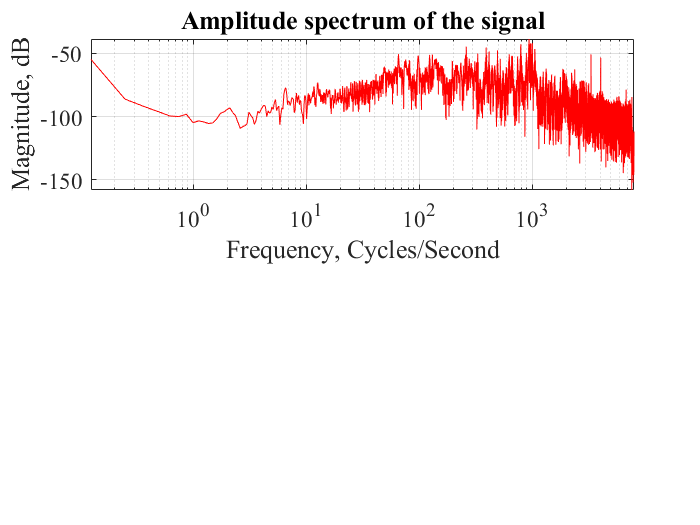

% code from https://www.mathworks.com/matlabcentral/answers/486379-frequency-spectrum-of-a-sound-signal
[y,fs] = audioread('PinkPanther16k.wav');
N = length(y);
t = (0:N-1/fs);
n = (0:N-1);
y = y(:,1);
% spectral analysis
w = hanning(N, 'periodic');
[X, f] = periodogram(y, w, N, fs, 'power');
X = 20*log10(sqrt(X)*sqrt(2));
% plot the signal spectrum
figure(1);
subplot(2,1,1);
semilogx(f, X, 'r');
xlim([0 max(f)]);
grid on;
set(gca, 'FontName', 'Times New Roman', 'FontSize', 14);
title('Amplitude spectrum of the signal');
xlabel('Frequency, Cycles/Second');
ylabel('Magnitude, dB');

function out = createChunks(audioIn, chunkDuration, overlapDuration, Nsamples, Duration)
    nChunks = CalcNChunks(chunkDuration, overlapDuration, Nsamples, Duration);
    chunkSamples = samplesInDuration(chunkDuration, Nsamples, Duration);
    stepSize = samplesInDuration(chunkDuration-overlapDuration, Nsamples, Duration);
    
    out = [];
    for index = 1:nChunks
        for sample = 1:1:chunkSamples
           ind = stepSize*(index-1) + sample;
           if ind > Nsamples
              out(index, sample) = 0; %padding zeroes for the remaining entries in the last chunk 
           else
              out(index, sample) = audioIn(ind); 
           end 
        end
        %disp(out);
    end
end

function nChunks = CalcNChunks(chunkDuration, overlapDuration, Nsamples, Duration)
    chunkSamples = samplesInDuration(chunkDuration, Nsamples, Duration);
    overlapSamples = samplesInDuration(overlapDuration, Nsamples, Duration);
    nChunks = 1 + ceil((Nsamples - chunkSamples)/(chunkSamples - overlapSamples));
    %disp(nChunks);
end


function samples = samplesInDuration(givenDuration, Nsamples, Duration)
    samples = round((givenDuration*Nsamples)/Duration);
    %disp(samples);
end
